% Solve for the coefficients of the CCM.
% We use monochrome and RGB values from 3 patches on a color chart.
% This gives us 3 matrices each with 3 unknowns and 3 equations to solve
% for all 9 coefficients in the CCM.
% Each equation is of the form Sc=b.
diary colorCorrectionLog
S_grayscaleMatrix = (255/100)*[
    31.0 31.0 31.0;
    43.0 43.0 43.0;
    25.0 25.0 25.0;
    ]

S_grayscaleMatrix =    79.0500   79.0500   79.0500
  109.6500  109.6500  109.6500
   63.7500   63.7500   63.7500


S_grayscaleMatrix = (255/100)*[
    31.0 0 0;
    0 43.0 0;
    0 0 25.0;
    ]

S_grayscaleMatrix =    79.0500         0         0
         0  109.6500         0
         0         0   63.7500



b_redMatrix = [166.0 65.0 51.0]';
b_greenMatrix = [41.0 145.0 58.0]';
b_blueMatrix = [56.0 65.0 144.0]';

c_redMatrix = S_grayscaleMatrix\b_redMatrix

c_redMatrix =     2.0999
    0.5928
    0.8000


c_greenMatrix = S_grayscaleMatrix\b_greenMatrix

c_greenMatrix =     0.5187
    1.3224
    0.9098


c_blueMatrix = S_grayscaleMatrix\b_blueMatrix

c_blueMatrix =     0.7084
    0.5928
    2.2588


grayImage = 535×850 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

colorCorrectionMatrix =     2.0999    0.5928    0.8000
    0.5187    1.3224    0.9098
    0.7084    0.5928    2.2588


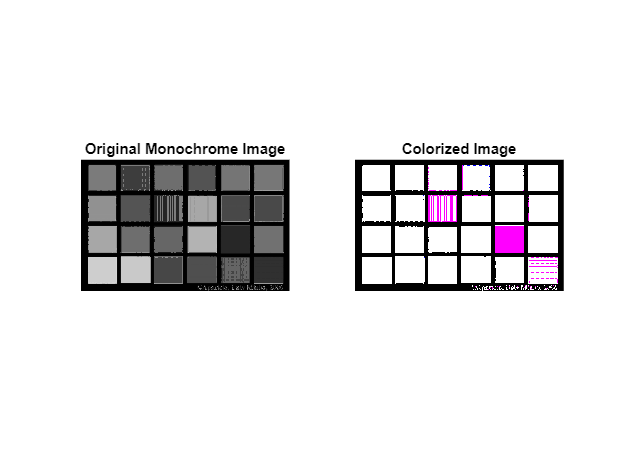


%transformImage(c_redMatrix, c_greenMatrix, c_blueMatrix)


% Show augmented matrix in rref. Visual verification if it is singular.
S_grayscaleMatrix(:,4) = b_redMatrix;
R = rref(S_grayscaleMatrix)

R =     1.0000         0         0    2.0999
         0    1.0000         0    0.5928
         0         0    1.0000    0.8000


% Try a least squares solution approach to obtain values
% for the coefficients.
% Add more rows to make this an overdetermined system.
% Ideally, all 24 patches would be measured.
% The value for monochrome in Paint.NET is 0-100.

S_grayscaleMatrix = (255/100)*[
    31.0 31.0 31.0;
    43.0 43.0 43.0;
    25.0 25.0 25.0;
    51.0 51.0 51.0;
    59.0 59.0 59.0;
    35.0 35.0 35.0;
    70.0 70.0 70.0;
    18.0 18.0 18.0;
    ]

S_grayscaleMatrix =    79.0500   79.0500   79.0500
  109.6500  109.6500  109.6500
   63.7500   63.7500   63.7500
  130.0500  130.0500  130.0500
  150.4500  150.4500  150.4500
   89.2500   89.2500   89.2500
  178.5000  178.5000  178.5000
   45.9000   45.9000   45.9000



b_redMatrix = [166.0 65.0 51.0 208.0 188.0 76.0 216.0 48.0]'

b_redMatrix =    166
    65
    51
   208
   188
    76
   216
    48


b_greenMatrix = [41.0 145.0 58.0 112.0 140.0 103.0 192.0 46.0]'

b_greenMatrix =     41
   145
    58
   112
   140
   103
   192
    46


b_blueMatrix = [56.0 65.0 144.0 36.0 121.0 60.0 27.0 46.0]'

b_blueMatrix =     56
    65
   144
    36
   121
    60
    27
    46



c_redMatrix = lsqr(S_grayscaleMatrix, b_redMatrix)

lsqr converged at iteration 1 to a solution with relative residual 0.29.


c_redMatrix =     0.4058
    0.4058
    0.4058


c_greenMatrix = lsqr(S_grayscaleMatrix, b_greenMatrix)

lsqr converged at iteration 1 to a solution with relative residual 0.18.


c_greenMatrix =     0.3341
    0.3341
    0.3341


c_blueMatrix = lsqr(S_grayscaleMatrix, b_blueMatrix)

lsqr stopped at iteration 1 without converging to the desired tolerance 1e-06
because a scalar quantity became too small or too large to continue computing.
The iterate returned (number 1) has relative residual 0.64.


c_blueMatrix =     0.1795
    0.1795
    0.1795



% transformImage(c_redMatrix, c_greenMatrix, c_blueMatrix)

% Test if tinting the image is possible.
b_redMatrix = [200 + zeros(1, 8)]'

b_redMatrix =    200
   200
   200
   200
   200
   200
   200
   200


b_greenMatrix = [50 + zeros(1, 8)]'

b_greenMatrix =     50
    50
    50
    50
    50
    50
    50
    50


b_blueMatrix = [200 + zeros(1, 8)]'

b_blueMatrix =    200
   200
   200
   200
   200
   200
   200
   200



c_redMatrix = lsqr(S_grayscaleMatrix, b_redMatrix)

lsqr converged at iteration 1 to a solution with relative residual 0.37.


c_redMatrix =     0.5436
    0.5436
    0.5436


c_greenMatrix = lsqr(S_grayscaleMatrix, b_greenMatrix)

lsqr converged at iteration 1 to a solution with relative residual 0.37.


c_greenMatrix =     0.1359
    0.1359
    0.1359


c_blueMatrix = lsqr(S_grayscaleMatrix, b_blueMatrix)

lsqr converged at iteration 1 to a solution with relative residual 0.37.


c_blueMatrix =     0.5436
    0.5436
    0.5436



% transformImage(c_redMatrix, c_greenMatrix, c_blueMatrix)

function process = transformImage(c_redMatrix, c_greenMatrix, c_blueMatrix)
% Read the monochrome image.
grayImage = imread('Reflective-color-chart-reference-BW.png')

% Define a color correction matrix for RGB color mapping.
% Simple example below.
colorCorrectionMatrix = [
    c_redMatrix'; % Red channel mapping
    c_greenMatrix'; % Green channel mapping
    c_blueMatrix'; % Blue channel mapping
    ]

% Get image dimensions.
[rows, cols] = size(grayImage);

% Initialize RGB image matrix.
rgbImage = zeros(rows, cols, 3);

% Apply color correction by looping over each pixel.
for i = 1:rows
    for j = 1:cols
        % Get grayscale value of current pixel.
        grayValue = double(grayImage(i, j)) / 255.0; % Normalize to [0,1]

        % Apply color correction matrix to map grayscale value to RGB
        % values
        rgbValue = colorCorrectionMatrix * [grayValue; grayValue; grayValue];
        
        % Store RBG values in the output image matrix.
        rgbImage(i, j, :) = uint8(rgbValue);
    end
end

% Display the original monochrome image and the transformed color image.
figure;
subplot(1, 2, 1);
imshow(grayImage);
title('Original Monochrome Image');

subplot(1, 2, 2);
imshow(rgbImage);
title('Colorized Image');

% Save the colorized image to a new file.
dt = datetime("now")
dt.Format = 'yyyyMMddHHMMSS';
filename = 'colorized_images/colorized_image_' + string(dt) + '.png'
imwrite(rgbImage, filename);

end